Круглый цилиндр, H-поляризация

По методу из гибсона для сравнения.

21_10_20

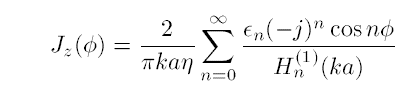

Гибсон стр 113

close all;
clear variables;

% исходные данные
% R = 2;
% N = 200;
% n_harmonic = 100; % кол-во гармоник
% 
% % константы
% eta = 120*pi;
% k = 2*pi; 

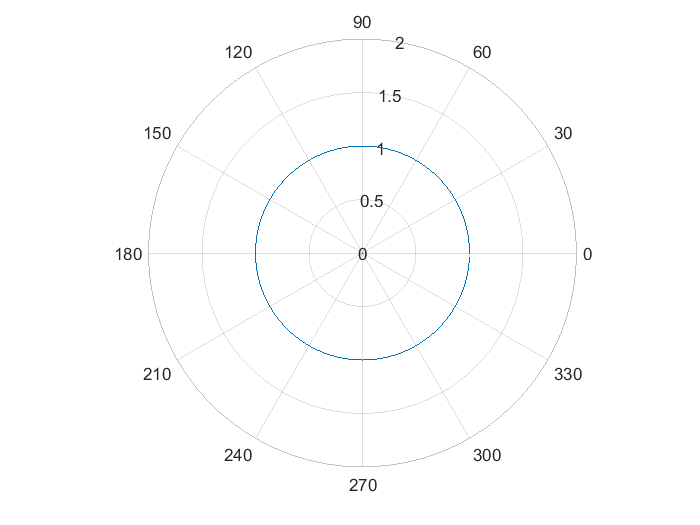

%%  1 - входные данные 

% Параметры среды-1
e1 = 20;
mu1 = 1;
k1 = 2*pi*sqrt(mu1*e1);
eta1 = 120*pi*sqrt(mu1/e1);

% Параметры среды-2
k2 = 2*pi;
eta2 = 120*pi;

% Параметры программы
a = 1;  % радиус круга
N_harm = 200; % количество гармоник
N_circl = 200; % количество точек на круга 
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]

% ========================================================================
% Построение круга
dphi_grad = 360/N_circl; % угловой шаг на круга [град]
dphi_rad = 2*pi/N_circl; % угловой шаг на круга [рад]

% получение векторов углов и вектора ридиусов
phi_circl_rad = zeros(1, N_circl);
phi_circl_grad = zeros(1, N_circl);
a_for_graph = zeros(1, N_circl);
for i = 1 : N_circl
    phi_circl_rad(i) = (i-1)*dphi_rad;
    phi_circl_grad(i) = (i-1)*dphi_grad;
    a_for_graph(i) = a;
end


% """график круга в полярных координатах"""
polarplot(phi_circl_rad, a_for_graph);

% Реальные токи 
I1 = zeros(1,N_circl);
I2 = zeros(1,N_circl);
% Поля
Es = zeros(1,N_circl);
Hs = zeros(1,N_circl);
Ep = zeros(1,N_circl);
Hp = zeros(1,N_circl);
% кол-во точек
for n_dot = 1 : N_circl
    
    % текужщий угол
    cur_phi = phi_circl_rad(n_dot);
      
    % кол-во гармоник
    j1_sum = 0;
    j2_sum = 0;
    Es_sum = 0;
    Hs_sum = 0;
    Ep_sum = 0;
    Hp_sum = 0; 
    for n = 1 : N_harm

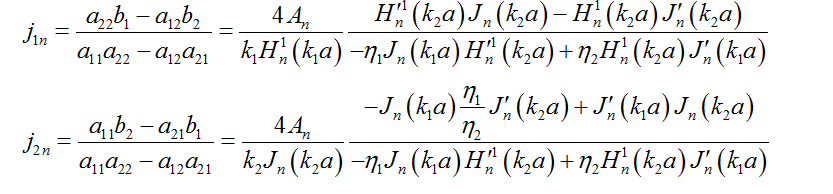

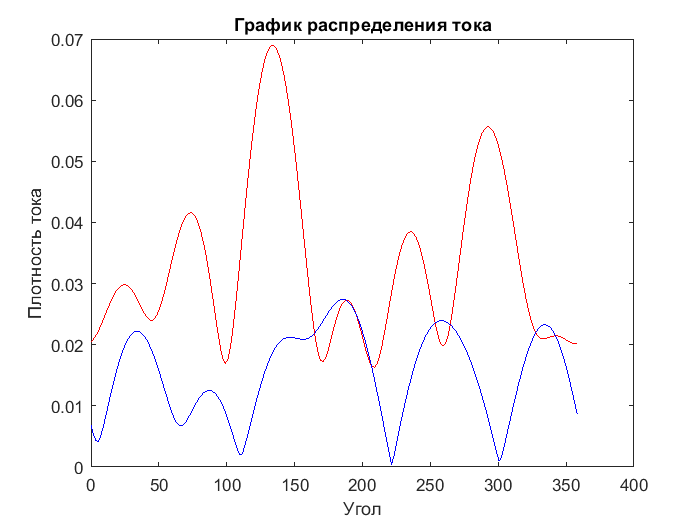

                
        An = ((-1)^n)*exp(-1i*n*phi_i_rad);       
        Z = -eta1*besselj(n,k1*a)*dH(n,k2*a) + eta2*besselh(n,1,k2*a)*dJ(n,k1*a);
        j1n = 4*An/(k1*besselh(n,1,k1*a)) * (dH(n,k2*a)*besselj(n,k2*a) - besselh(n,1,k2*a)*dJ(n,k2*a))/Z;
        j2n = 4*An/(k2*besselj(n,k2*a)) * (-eta1/eta2*besselj(n,k1*a)*dJ(n,k2*a) + dJ(n,k1*a)*besselj(n,k2*a))/Z;
        
        % суммарный ток при заданой угле на цилиндре
        j1_sum = j1_sum + j1n*exp(1j*n*cur_phi);
        j2_sum = j2_sum + j2n*exp(1j*n*cur_phi);
        
        % посчитаем поле на растоянии r = 2a
        ro = 2*a;

        % Рассеянное поле
        Es_sum = Es_sum - k2/4*eta2*j2n*besselh(n,1,k2*ro)*besselj(n,k2*a)*exp(1i*n*cur_phi);
        Hs_sum = Hs_sum - k2*1j/4*j2n*dH(n,k2*ro)*besselj(n,k2*a)*exp(1i*n*cur_phi);
        % прошедшее поле
        Ep_sum = Ep_sum - k1/4*eta1*j1n*besselh(n,1,k1*a)*besselj(n,k1*ro)*exp(1i*n*cur_phi);
        Hp_sum = Hp_sum - k1*1j/4*j1n*besselh(n,1,k1*a)*dJ(n,k1*ro)*exp(1i*n*cur_phi);
        
    end
    
    % сохранение тока от угла
    I1(n_dot) = j1_sum; 
    I2(n_dot) = j2_sum;
    
    % сохранение поля от угла
    Es(n_dot) = Es_sum;
    Hs(n_dot) = Hs_sum;
    Ep(n_dot) = Ep_sum;
    Hp(n_dot) = Hp_sum; 
end


% графики токов
plot(phi_circl_grad, abs(I1),'r',phi_circl_grad, abs(I2),'b')
title('График распределения тока'); 
xlabel('Угол'); 
% xlim([0,360])
ylabel('Плотность тока');

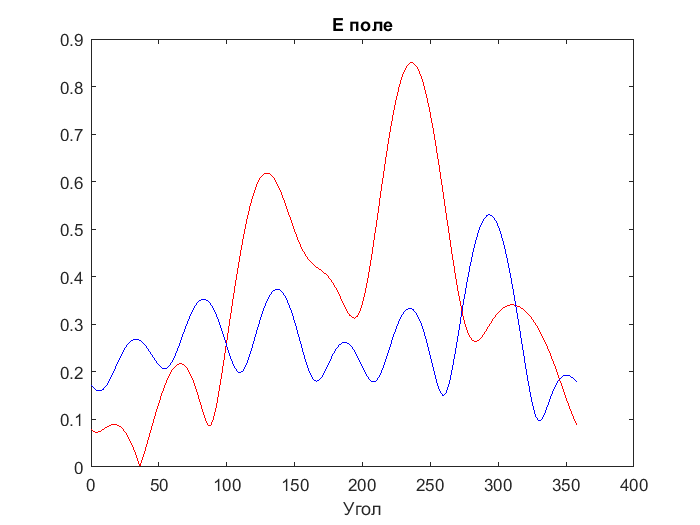


% графики полей 
plot(phi_circl_grad, abs(Es),'r',phi_circl_grad, abs(Ep),'b')
title('E поле'); 
xlabel('Угол'); 
ylabel('');

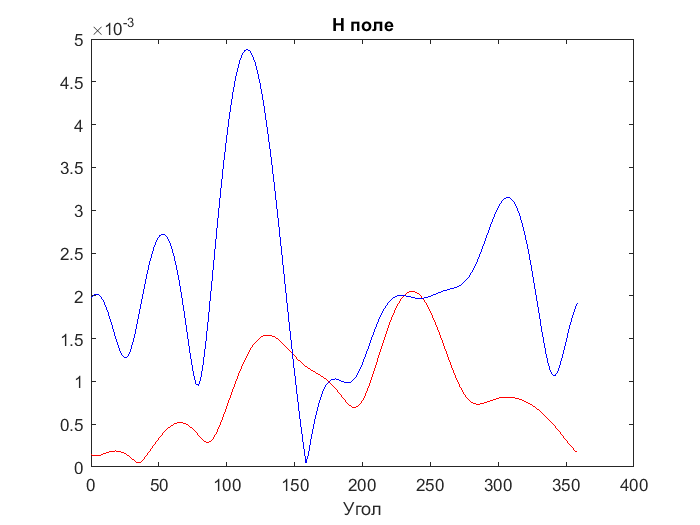


% графики полей 
plot(phi_circl_grad, abs(Hs),'r',phi_circl_grad, abs(Hp),'b')
title('H поле'); 
xlabel('Угол'); 
ylabel('');

Полярные графики полей

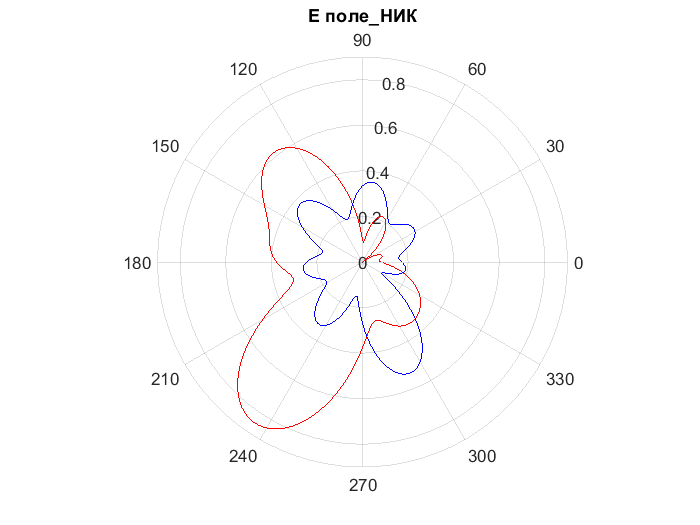

% графики полей 
polarplot(phi_circl_rad, abs(Es),'r',phi_circl_rad, abs(Ep),'b')
title('E поле\_НИК'); 

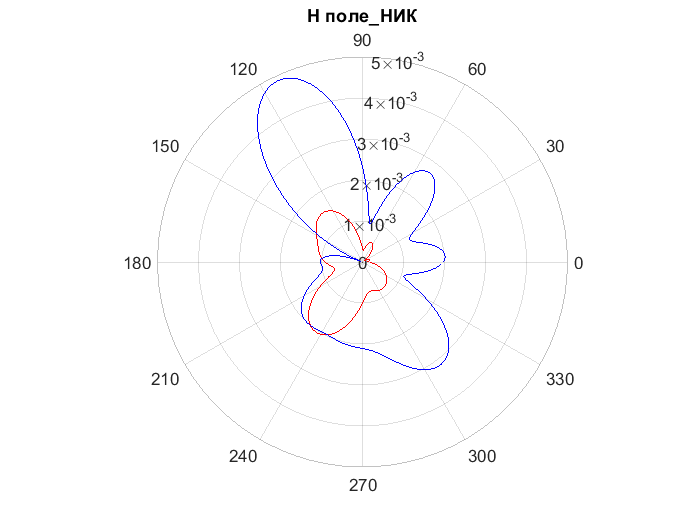



% графики полей 
polarplot(phi_circl_rad, abs(Hs),'r',phi_circl_rad, abs(Hp),'b')
title('H поле\_НИК'); 

## Метод 2 - Никольский

% 4 - посчитаем поле методом никольского на растоянии ro = 2*a
    
% растояние на котром будем смотреть поле
ro = 2*a;

Es_NIC = zeros(1,N_circl);
Hs_NIC = zeros(1,N_circl);
Ep_NIC = zeros(1,N_circl);
Hp_NIC = zeros(1,N_circl);

for n_dot = 1 : N_circl
    
    % текужщий угол
    cur_phi = phi_circl_rad(n_dot);
    
    Es_sum = 0;
    Hs_sum = 0;
    Ep_sum = 0;
    Hp_sum = 0; 
    for n = 1 : N_harm
        
        An = (-1)^n;       
        Z2 = besselj(n,k1*a)*dH(n,k2*a) - eta2/eta1*besselh(n,1,k2*a)*dJ(n,k1*a);     
        bn = An * (dH(n,k2*a)*besselj(n,k2*a) - besselh(n,1,k2*a)*dJ(n,k2*a))/Z2;
        cn = An * (-besselj(n,k1*a)*dJ(n,k2*a) + eta2/eta1*dJ(n,k1*a)*besselj(n,k2*a))/Z2;

        % отраженое поле
        Es_sum = Es_sum + cn*besselh(n,1,k2*ro)*exp(1i*n*cur_phi);
        Hs_sum = Hs_sum + 1i/eta2*cn*dH(n, k2*ro)*exp(1i*n*cur_phi);
        
        % прошедшее поле
        Ep_sum = Ep_sum + bn*besselj(n, k1*ro)*exp(1i*n*cur_phi);
        Hp_sum = Hp_sum + 1i/eta1*bn*dJ(n, k1*ro)*exp(1i*n*cur_phi);
        
    end
    Es_NIC(n_dot) = Es_sum;
    Hs_NIC(n_dot) = Hs_sum;
    Ep_NIC(n_dot) = Ep_sum;
    Hp_NIC(n_dot) = Hp_sum;
end

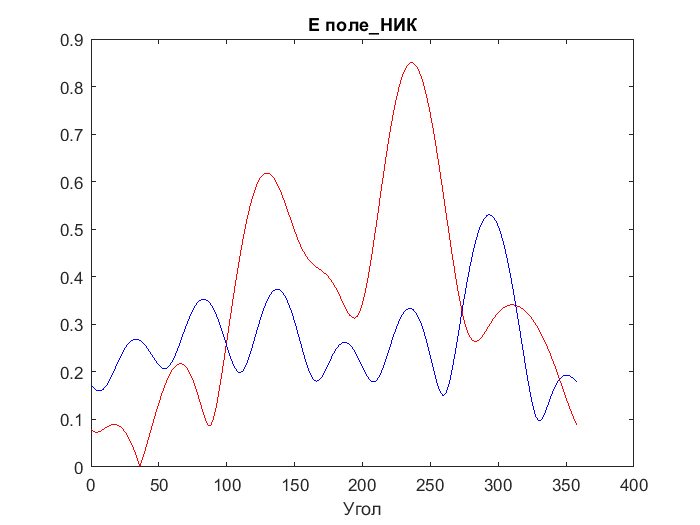

% графики полей 
plot(phi_circl_grad, abs(Es_NIC),'r',phi_circl_grad, abs(Ep_NIC),'b')
title('E поле\_НИК'); 
xlabel('Угол'); 
ylabel('');

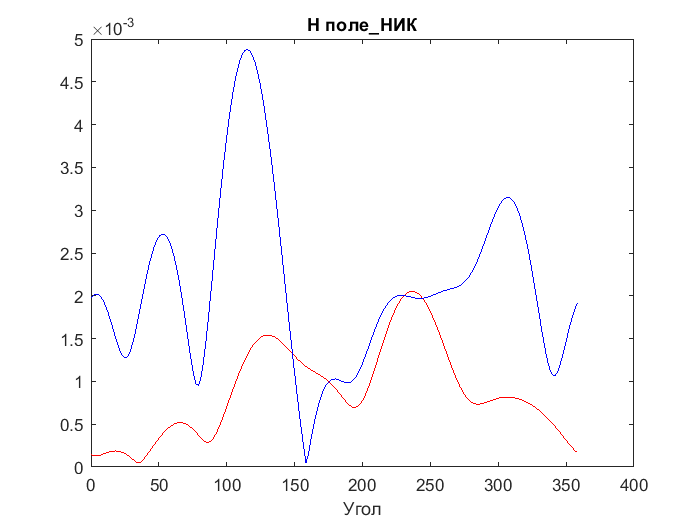


% графики полей 
plot(phi_circl_grad, abs(Hs_NIC),'r',phi_circl_grad, abs(Hp_NIC),'b')
title('H поле\_НИК'); 
xlabel('Угол'); 
ylabel('');

Полярные графики полей

% графики полей 
polarplot(phi_circl_rad, abs(Es_NIC),'r',phi_circl_rad, abs(Ep_NIC),'b')
title('E поле\_НИК'); 



% графики полей 
polarplot(phi_circl_rad, abs(Hs_NIC),'r',phi_circl_rad, abs(Hp_NIC),'b')
title('H поле\_НИК'); 

function [dJ_calc] = dJ(n,x)
    dJ_calc = n/x*besselj(n,x) - besselj(n+1,x);
end
function [dH_calc] = dH(n,x)
    dH_calc = n/x*besselh(n,1,x) - besselh(n+1,1,x);
end